## **Przetwarzanie Sygnałów Cyfrowych**

# **Filtracja sygnałów, Filtry IIR**

## Jan Rosa 410269 AiR

### Zadania do wykonania

W sprawozdaniu powinny znaleźć się:

1) Informacje na temat w jaki sposób projektujemy filtry IIR.

2) Różnice między filtrami FIR i IIR.

3) Wykonane zadania - skrypty w m.plikach oraz otrzymane wykresy.

4) Wnioski z przeprowadzonych zadań.

### Zad. 1

Korzystając z Przykładu 4 zaprojektować filtr IIR:

[b,a] = maxflat(4,1,0.3)

oraz

maxflat(4,'sym',0.3)

[b,a] = maxflat(4,1,0.3);
fvtool(b,a)

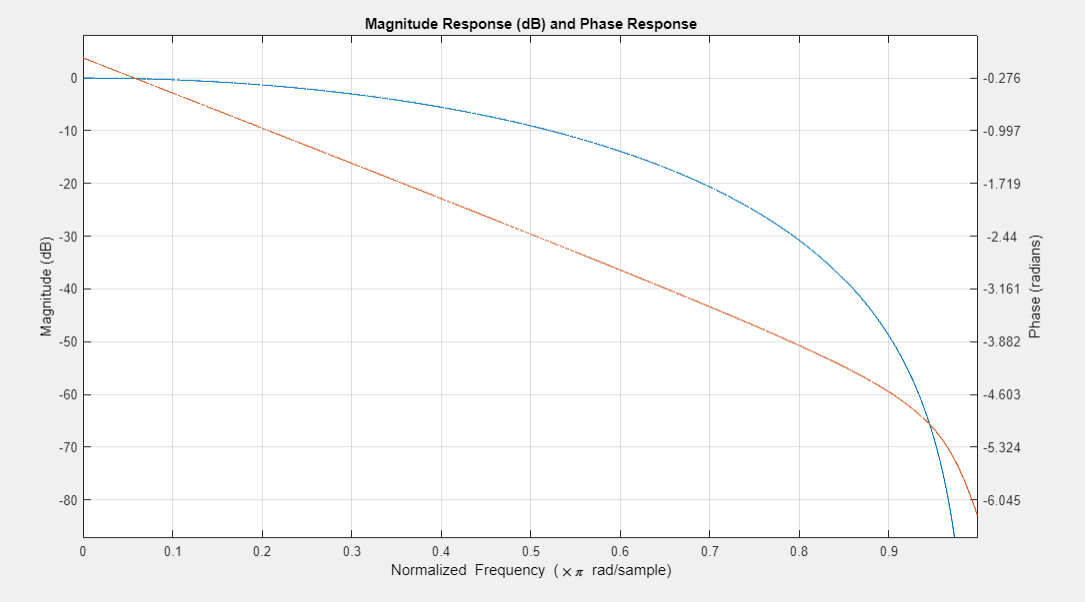

[b,a] = maxflat(4,'sym',0.3);
fvtool(b,a)

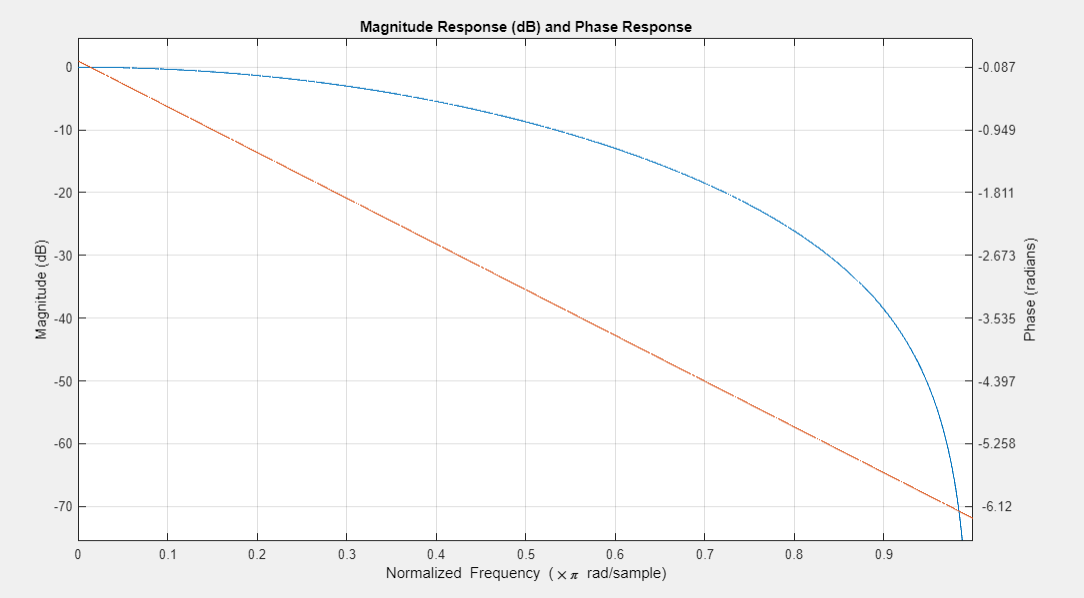

### Zad2

Sprawdzić stabilność filtru o współczynnikach 

b = [1 -0.5]; a = [1 -2];
isstable(b,a)

ans = logical
   0


### Zad3

Sprawdzić stabilność filtru o współczynnikach 

b = [1 -0.1]; a = [-1 -0.1];
isstable(b,a)

ans = logical
   1


### Zad4

Sprawdzić stabilność filtru o współczynnikach

b = [0.9 -0.8]; a = [-0.9 -0.8];
isstable(b,a)

ans = logical
   1


### Zad5

Sprawdzić stabilność filtru o współczynnikach

b = [0.9 -0.8 1 1]; a = [-0.9 -0.8 -1];
isstable(b,a)

ans = logical
   0


### Zad6

Sprawdzić stabilność następującego filtru

m = [0 0 1 1 1 0 1 1 0 0];
f = [0 0.1 0.2 0.3 0.4 0.5 0.7 0.8 0.9 1];
[b, a] = yulewalk(10, f, m);
isstable(b,a)

ans = logical
   1


### Zad7

Przefiltrować sygnał chirp filtrem IIR maxflat(4,1,0.3). Narysować przebieg

czasowy i częstotliwościowy przefiltrowanego sygnału.

[b, a] = maxflat(4,1,0.3);
act_flag1 = isstable(b,a)

act_flag1 = logical
   1


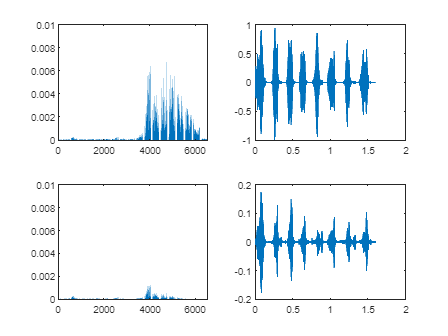

%zplane(b,a)
% wynik flag = 0
load chirp
t = (0:length(y)-1)/Fs;
% 1.6 sekundy
xfft=abs(fft(y));
xfft=xfft/13129;
x1=1:1:6564;
figure
subplot(2,2,1)
bar(x1(1:6564), xfft(1:6564));
axis([0,6564, 0,0.01]) ;
subplot(2,2,2)
plot(t,y);
outsignal = filter(b,a,y);
subplot(2,2,4)
plot(t, outsignal);
xfft=abs(fft(outsignal));
xfft=xfft/13129;
x1=1:1:6564;
subplot(2,2,3)
bar(x1(1:6564), xfft(1:6564));
axis([0,6564, 0,0.01]) ;

### Zad8

Przefiltrować sygnał chirp filtrem IIR

m = [0 0 0 0 0 1 1 1 1 1];
f = [0 0.1 0.2 0.3 0.4 0.5 0.7 0.8 0.9 1];
[b,a] = yulewalk(10,f,m);
act_flag1 = isstable(b,a)

act_flag1 = logical
   1


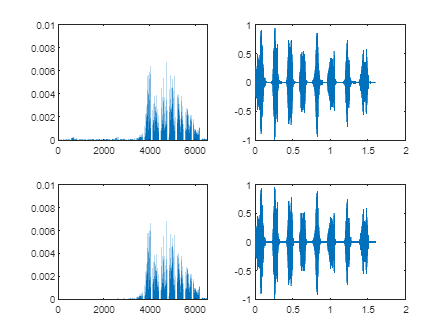

%zplane(b,a)
% wynik flag = 0
%fvtool(b,a)
load chirp
t = (0:length(y)-1)/Fs;
% 1.6 sekundy
xfft=abs(fft(y));
xfft=xfft/13129;
x1=1:1:6564;
figure
subplot(2,2,1)
bar(x1(1:6564), xfft(1:6564));
axis([0,6564, 0,0.01]) ;
subplot(2,2,2)
plot(t,y);
outsignal = filter(b,a,y);
subplot(2,2,4)
plot(t, outsignal);
xfft=abs(fft(outsignal));
xfft=xfft/13129;
x1=1:1:6564;
subplot(2,2,3)
bar(x1(1:6564), xfft(1:6564));
axis([0,6564, 0,0.01]) ;

Zad 9

Przefiltrować sygnał chirp filtrem IIR. Uwaga filtr jest niestabilny.

b = [0.9 -0.8 1 1]; a = [-0.9 -0.8 -1];

Narysować przebieg czasowy i częstotliwościowy przefiltrowanego sygnału.

Narysować charakterystykę częstotliwościową filtru.

b = [0.9 -0.8 1 1]; a = [-0.9 -0.8 -1];
act_flag1 = isstable(b,a)

act_flag1 = logical
   0


%zplane(b,a)
% wynik flag = 0
%fvtool(b,a)

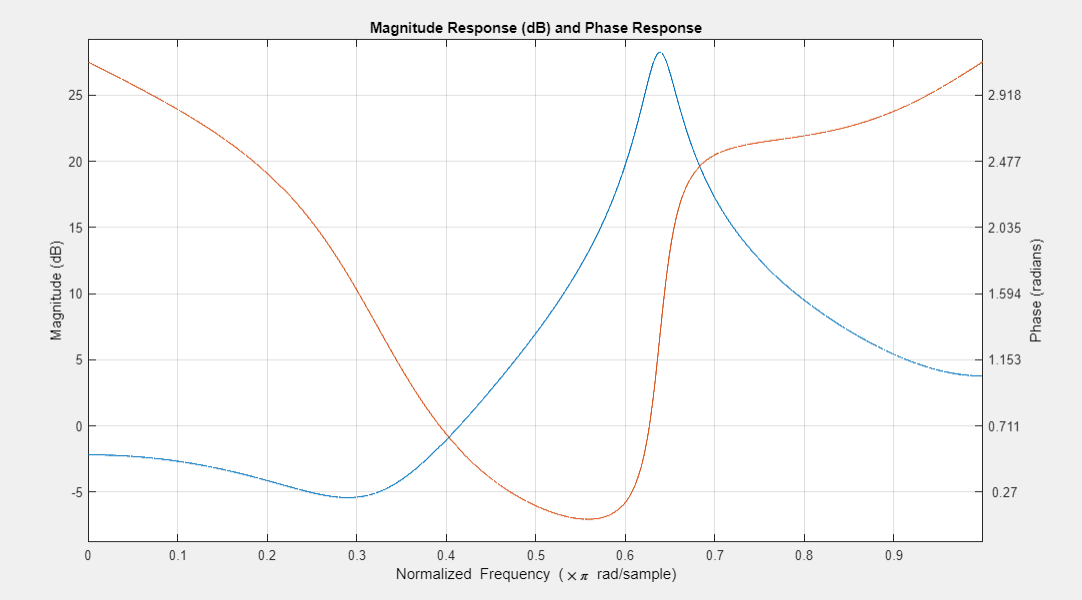

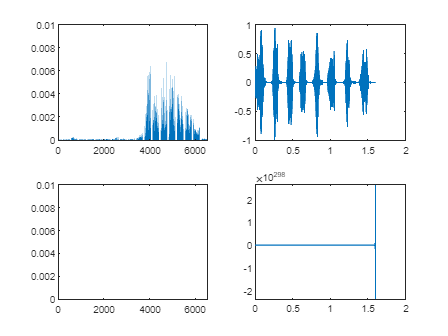

load chirp
t = (0:length(y)-1)/Fs;
% 1.6 sekundy
xfft=abs(fft(y));
xfft=xfft/13129;
x1=1:1:6564;

figure
subplot(2,2,1)
bar(x1(1:6564), xfft(1:6564));
axis([0,6564, 0,0.01]) ;

subplot(2,2,2)
plot(t,y);
outsignal = filter(b,a,y);

subplot(2,2,4)
plot(t, outsignal);
xfft=abs(fft(outsignal));
xfft=xfft/13129;
x1=1:1:6564;

subplot(2,2,3)
bar(x1(1:6564), xfft(1:6564));
axis([0,6564, 0,0.01]) ;

### Zad 10

Przefiltrować sygnał chirp filtrem IIR, Butterwortha. Użyć funkcji buttord i butter.

z parametrami

[n,Wn] = buttord([2000 3000]/5000,[500 4500]/5000,1,60);
[b, a] = butter(n, Wn);
act_flag1 = isstable(b,a)

act_flag1 = logical
   1


%zplane(b,a)
% wynik flag = 0
%fvtool(b,a)

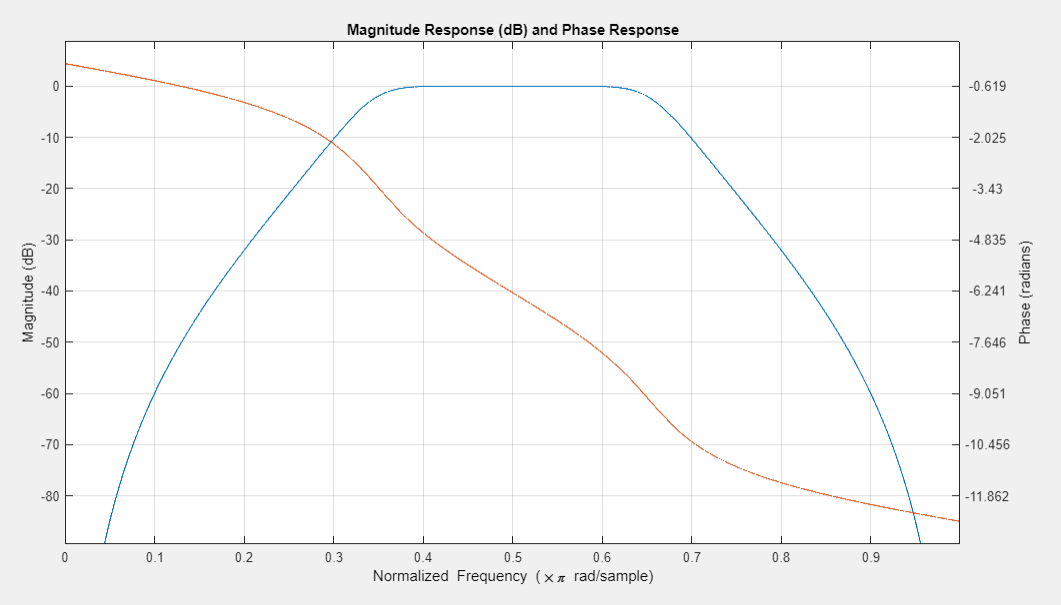

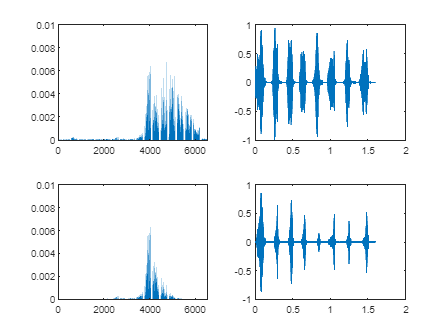

load chirp
t = (0:length(y)-1)/Fs;
% 1.6 sekundy
xfft=abs(fft(y));
xfft=xfft/13129;
x1=1:1:6564;

figure
subplot(2,2,1)
bar(x1(1:6564), xfft(1:6564));
axis([0,6564, 0,0.01]) ;

subplot(2,2,2)
plot(t,y);
outsignal = filter(b,a,y);

subplot(2,2,4)
plot(t, outsignal);
xfft=abs(fft(outsignal));
xfft=xfft/13129;
x1=1:1:6564;

subplot(2,2,3)
bar(x1(1:6564), xfft(1:6564));
axis([0,6564, 0,0.01]) ;

### Zad 11

Przefiltrować sygnał chirp filtrem IIR, Butterwortha. Użyć funkcji buttord i butter.

z parametrami

[n,Wn] = buttord([2000 3000]/5000,[1800 3200]/5000,1,60);
[b, a] = butter(n, Wn);
act_flag1 = isstable(b,a)

act_flag1 = logical
   1


%zplane(b,a)
% wynik flag = 0
%fvtool(b,a)

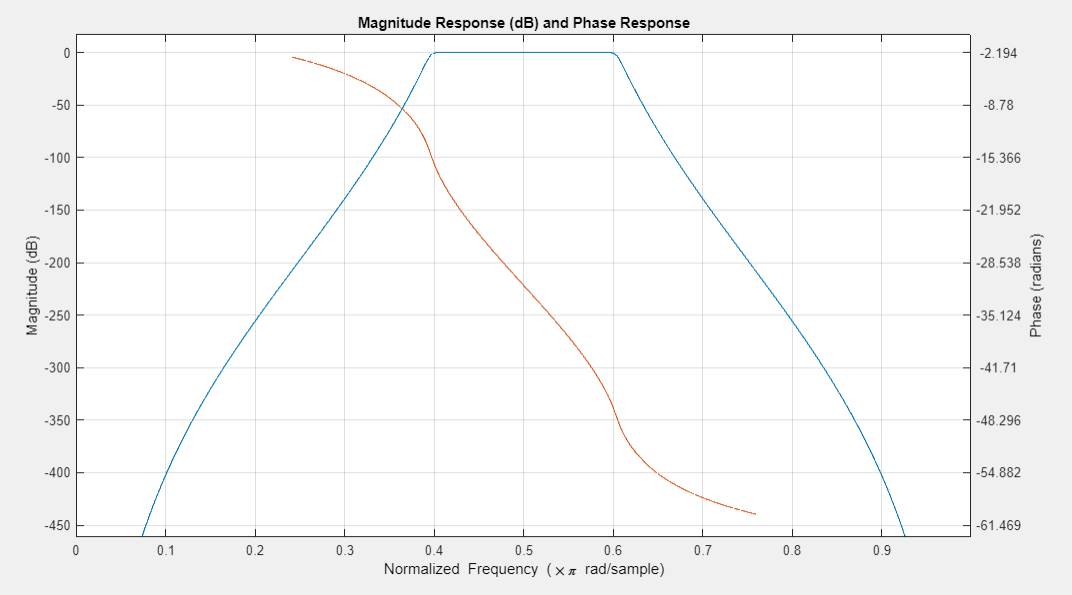

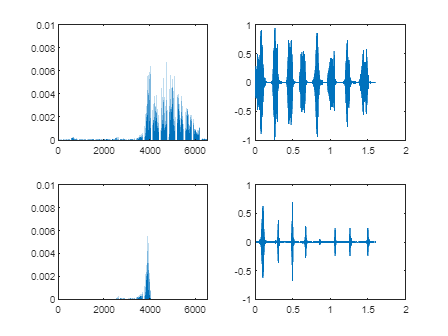

load chirp
t = (0:length(y)-1)/Fs;
% 1.6 sekundy
xfft=abs(fft(y));
xfft=xfft/13129;
x1=1:1:6564;

figure
subplot(2,2,1)
bar(x1(1:6564), xfft(1:6564));
axis([0,6564, 0,0.01]) ;

subplot(2,2,2)
plot(t,y);
outsignal = filter(b,a,y);

subplot(2,2,4)
plot(t, outsignal);
xfft=abs(fft(outsignal));
xfft=xfft/13129;
x1=1:1:6564;

subplot(2,2,3)
bar(x1(1:6564), xfft(1:6564));
axis([0,6564, 0,0.01]) ;

### Zad 12

Przefiltrować sygnał chirp filtrem IIR, Butterwortha. Użyć funkcji ellipord i ellip.

z parametrami

[n,Wn] = ellipord([2200 2700]/5000,[2000 2900]/5000,1,60);
[b, a] = ellip(n,1 , 60, Wn);
act_flag1 = isstable(b,a)

act_flag1 = logical
   1


%zplane(b,a)
%wynik flag = 0
fvtool(b,a)

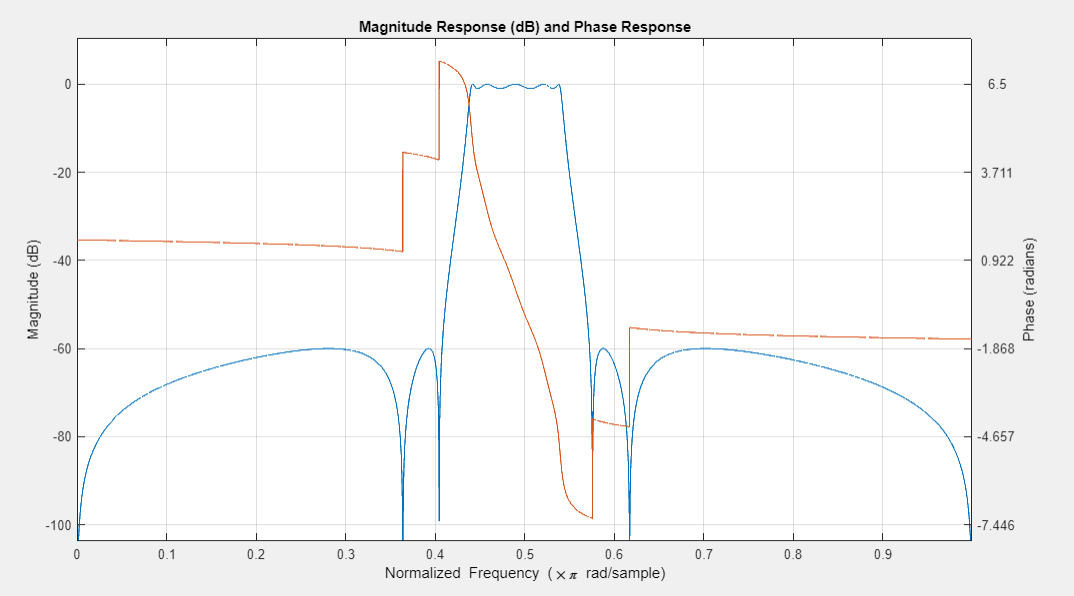

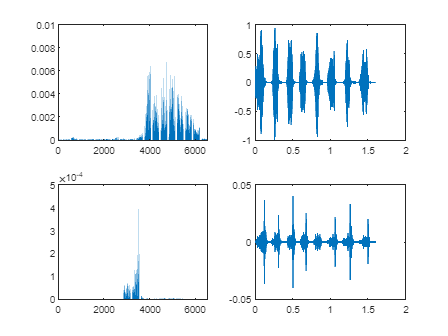

load chirp
t = (0:length(y)-1)/Fs;
% 1.6 sekundy
xfft=abs(fft(y));
xfft=xfft/13129;
x1=1:1:6564;

figure
subplot(2,2,1)
bar(x1(1:6564), xfft(1:6564));
axis([0,6564, 0,0.01]) ;

subplot(2,2,2)
plot(t,y);
outsignal = filter(b,a,y);

subplot(2,2,4)
plot(t, outsignal);
xfft=abs(fft(outsignal));
xfft=xfft/13129;
x1=1:1:6564;

subplot(2,2,3)
bar(x1(1:6564), xfft(1:6564));